# **Homework n°2 2022/2023**

### *Del Prete Rocco 0124002592*

Imposto il formato `long` per la visualizzazione dei dati.

format long

### Punto 1 – Interpolazione:

«*Definire un dominio *$[a,b]$* ed una funzione composta *$f(x)$* in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale *$f$*sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB ezplot per osservarne il grafico. *

*Definire quindi un insieme di *$m$* punti *$P=\{(x_i,y_i)\}_{i=1}^m$* con *$11 \leq m \leq 21, m \in \mathbb{N}$*. Le ascisse di *$P$* sono linearmente distribuite in *$[a,b]$*, le ordinate sono i corrispondenti valori assunti dalla valutazione di *$f(x)$*.*»

Definisco una funzione $f(x) = \log(e^x + 1) + 2 \sin(x)$ in un intervallo $[0, 18]$.

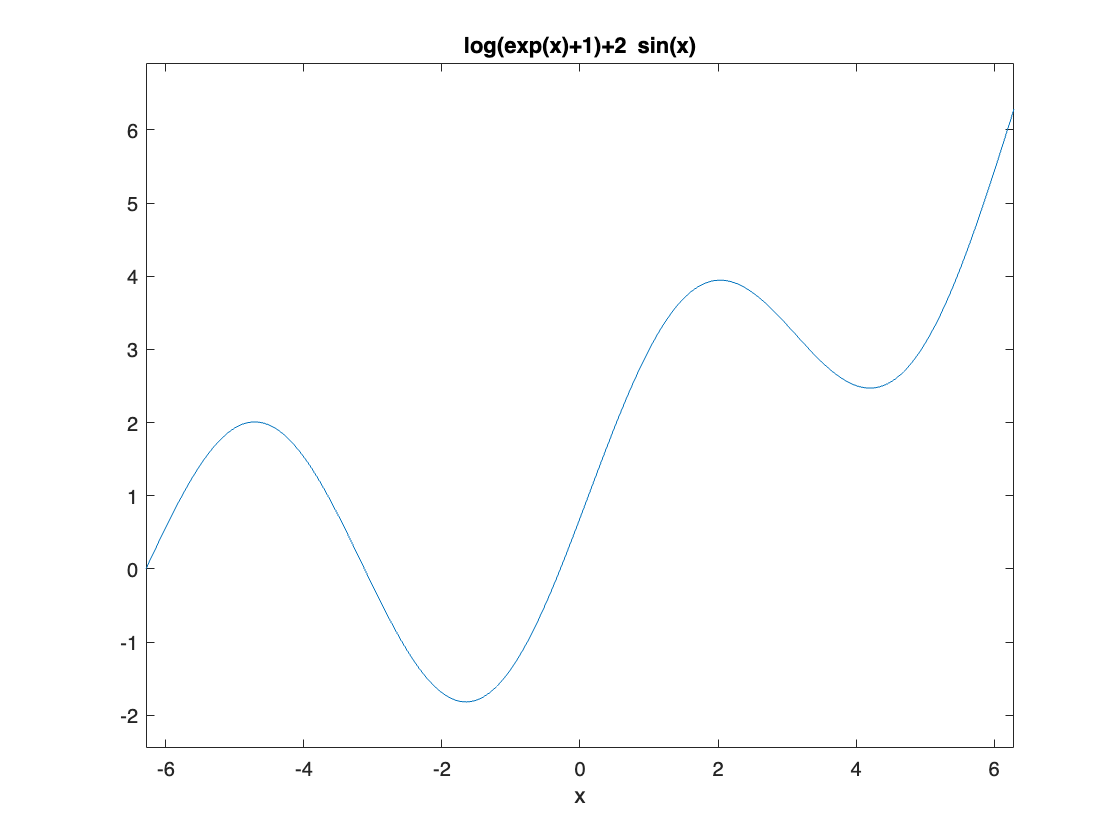

f = @(x) log(exp(x) + 1) + 2 * sin(x);
figure(1)
ezplot(f)

a1 = 0; % Estremo sinistro
b1 = 18; % Estremo destro
figure(2)
fplot(f, [a1, b1])
hold on
grid on
axis([a1 - 0.2, b1 + 0.2, 1, 20])
title('f(x)')
xlabel('Asse x')
ylabel('Asse y')

Definisco adesso i nodi ed i valori:

m = 11; % Numero di nodi
h = (b1 - a1) / (m - 1); % Passo di incremento
x = (a1:h:b1)'; % Nodi
clear h % Non ci serve più
y = f(x); % Calcolo dei valori

#### Punto 1.1:

«*Definire un insieme *$\mathcal{F}$*di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio *$p$  $\in$ $\mathcal{F}$* che interpola *$f$* nei nodi *$x_i$*. Costruire il relativo sistema lineare *$Ba=y$* e risolverlo (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice *$B$*.*»

Come funzione di base utilizzo $x^{(j-1)}$. Prealloco la matrice attraverso la funzione `ones` in modo da aumentare la velocità di esecuzione. Il `for` lo faccio partire da 2, in quanto se lo volessi far partire da 1 avrei delle operazioni inutili (siccome la prima colonna della *matrice di Vandermonde *è composta da soli $x^0$ e quindi da tutti 1).

b = @(x, j) x.^(j - 1);
B = ones(m,m);
for j = 2 : m
    B(:, j) = b(x, j);
end

fprintf('Il rango della matrice è: %d\nIl determinante della matrice è: %d', rank(B), det(B));

Il rango della matrice è: 11
Il determinante della matrice è: 7.300812e+41

Come è possibile vedere, il rango della matrice è massimo ed il determinante è diverso da zero: la matrice è quindi **non-singolare**.

a = SGauss(B, y);
cond(B) % Visualizziamo l'indice di condizionamento

ans =      4.057899978275573e+14


L'indice di condizionamento è elevato, ciò è corretto in quanto il sistema di riferimento è un sistema lineare con matrice 11x11.

#### Punto 1.2:

«*Valutare il polinomio *$p$* su una griglia di *$N$* punti di valutazione distribuiti casualmente in *$[a,b]$*. Fissare *$N\,\,( 201 \leq N \leq 399)$*. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.*»

Come numero di punti di valutazioni ho scelto 300. Definiamo quindi una griglia di punti di valutazione.

xx = a1 + (b1 - a1) * rand(300, 1);
xx = sort(xx);

Genero una matrice di Vandermonde le cui entrate sono le valutazioni delle funzioni `b(x)` sui punti di valutazione `xx`.

BB = ones(length(xx), m);
for j = 2 : m
    BB(:, j) = b(xx, j);
end

Otteniamo i valori del polinomio interpolante sulla griglia $xx$ dal prodotto matrice-vettore $BB \cdot a$.

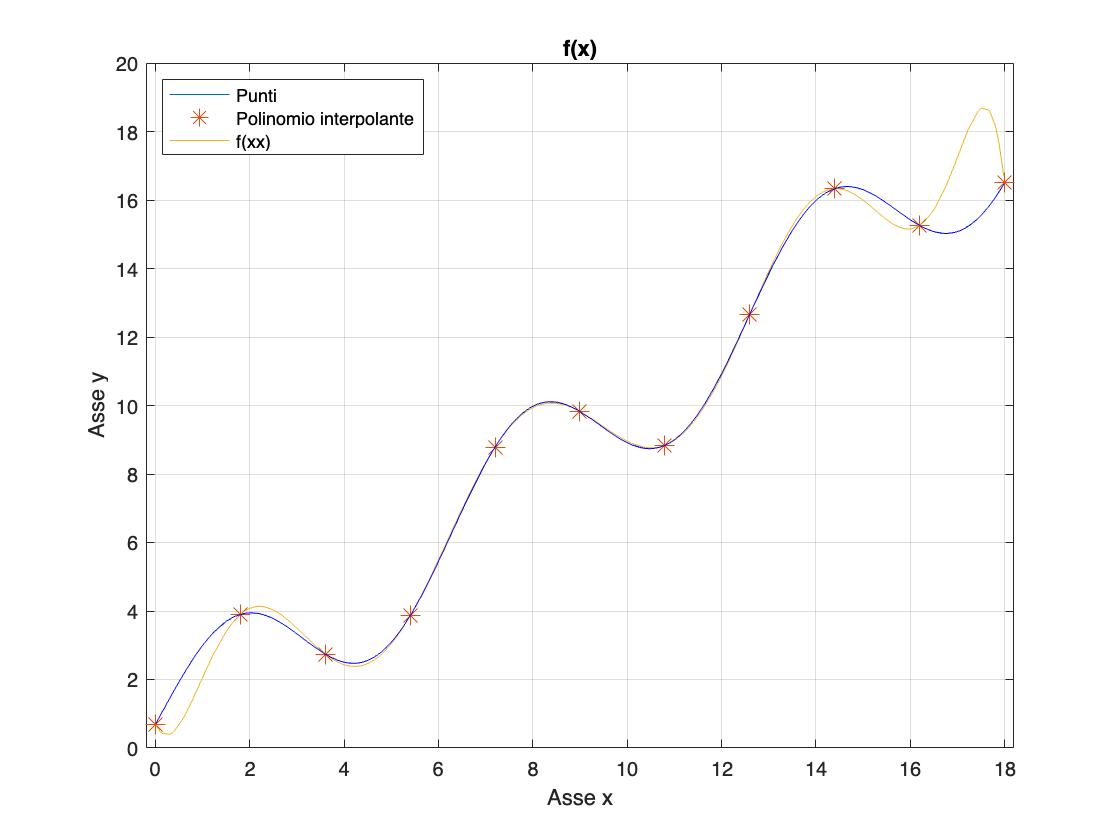

yy = BB * a; % Prodotto matrice-vettore
figure(3)
plot(x, y, '*', 'MarkerSize', 10)
hold on
grid on
axis([a1 - 0.2, b1 + 0.2, 0, 20])
plot(xx, yy)
plot(xx, f(xx), 'b')
xlabel('Asse x')
ylabel('Asse y')
legend('Punti', 'Polinomio interpolante', 'f(xx)', 'Location', 'northwest')
hold off

errInt = abs(yy - f(xx))

errInt =    0.050677064518189
   0.109907849313153
   0.555504206355357
   1.061976374910065
   1.136746422921443
   1.199804858710924
   1.273825494547691
   1.272909270949681
   1.270136332241454
   1.259127474540008


Vediamo come l'errore di interpolazione sia, per le varie componenti, tutto sommato accettabile, con però dei valori più alti vicino agli estremi.

#### Punto 1.3:

*«Interpolare i punti *$P$* mediante una spline *$s$* di terzo grado di tipo not-a-knot.  Valutare l'interpolante ottenuto sulla griglia di *$N$* punti di valutazione del punto 1.2.*»

Attraverso la funzione `spline` otteniamo una spline not-a-knot; `ppval` ci consente invece di valutare un polinomio a tratti su un insieme di ascisse, che costuiscono la nostra griglia di valutazione.

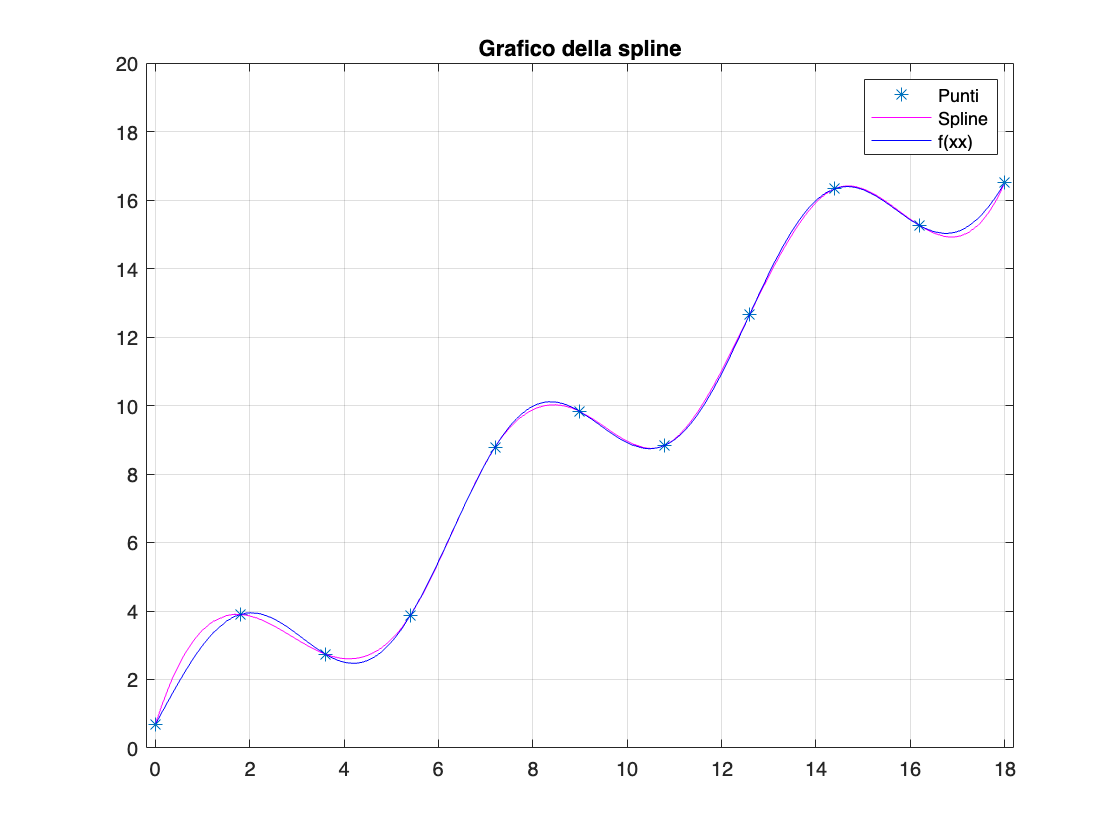

pp = spline(x, y);
yy_spline = ppval(pp, xx);
figure(4)
plot(x, y, '*', 'MarkerSize', 7)
hold on
grid on
axis([a1 - 0.2, b1 + 0.2, 0, 20])
plot(xx, yy_spline, 'm', 'MarkerSize', 7)
plot(xx, f(xx), 'b', 'MarkerSize', 7)
title('Grafico della spline')
legend('Punti', 'Spline', 'f(xx)')
hold off

Come era immaginabile la spline approssima meglio la nostra funzione di riferimento.

#### Punto 1.4:

«*Fissare un valore *$n\,\,( 10 \leq n \leq 19)$* e definire un nuovo insieme di punti *$Q = \{(x_j, y_j)\}_{j=1}^n$* le cui ascisse sono i nodi di Chebyshev in *$[a,b]$* e le cui ordinate sono i valori corrispondenti assunti da *$f(x)$*. Costruire il polinomio interpolante i punti *$Q$* e valutarlo sulla griglia di valutazione generata al punto 1.2.*»

Come numero di punti ho scelto 10. I nodi di Chebychev non sono equispaziati, ma sono più fitti agli estremi e meno al centro dell'intervallo in cui sono definiti (ovvero $[-1, 1]$). I nodi sono definiti come $x_k = cos\Big(\frac{k}{n-1}\pi\Big) \quad k=0,\ldots,n$. Ho messo "-" prima del coseno per ordinarli in ordine crescente. Ad ogni modo, questi nodi possono essere traslati per il nostro intervallo.

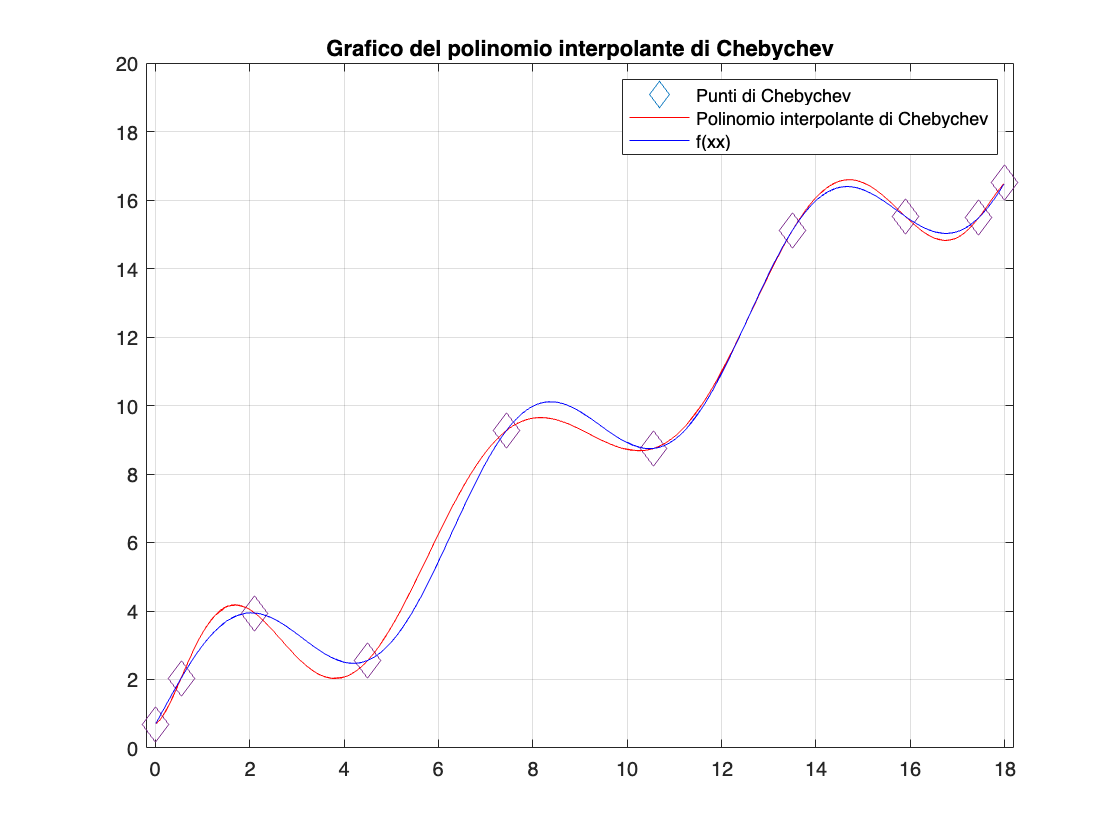

n = 10;
xc = -cos((0 : n - 1) * pi/(n - 1));
x_cheb = ((a1 + b1) / 2 + (b1 - a1) / 2 * xc)'; % Nodi di Chebychev traslati
y_cheb = f(x_cheb); % Valutazione

% Ripetiamo i procedimenti di prima ma per i nodi di Chebychev
B_cheb = ones(n, n);
for j = 1 : n
    B_cheb(:, j) = b(x_cheb, j);
end
a_cheb = SGauss(B_cheb, y_cheb);

BB_cheb = ones(300, n);
for j = 1 : n
    BB_cheb(:, j) = b(xx, j);
end
yy_cheb = BB_cheb * a_cheb;
figure(5)
plot(x_cheb, y_cheb, 'd', 'MarkerSize', 12)
hold on
grid on
axis([a1 - 0.2, b1 + 0.2, 0, 20])
plot(xx, yy_cheb, 'r', 'MarkerSize', 7)
plot(xx, f(xx), 'b', 'MarkerSize', 7)
title('Grafico del polinomio interpolante di Chebychev')
legend('Punti di Chebychev', 'Polinomio interpolante di Chebychev', 'f(xx)')

Possiamo vedere che l'errore agli estremi si è ridotto, tuttavia è aumentato al centro dell'intervallo.

#### Punto 1.5:

«*Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.*»

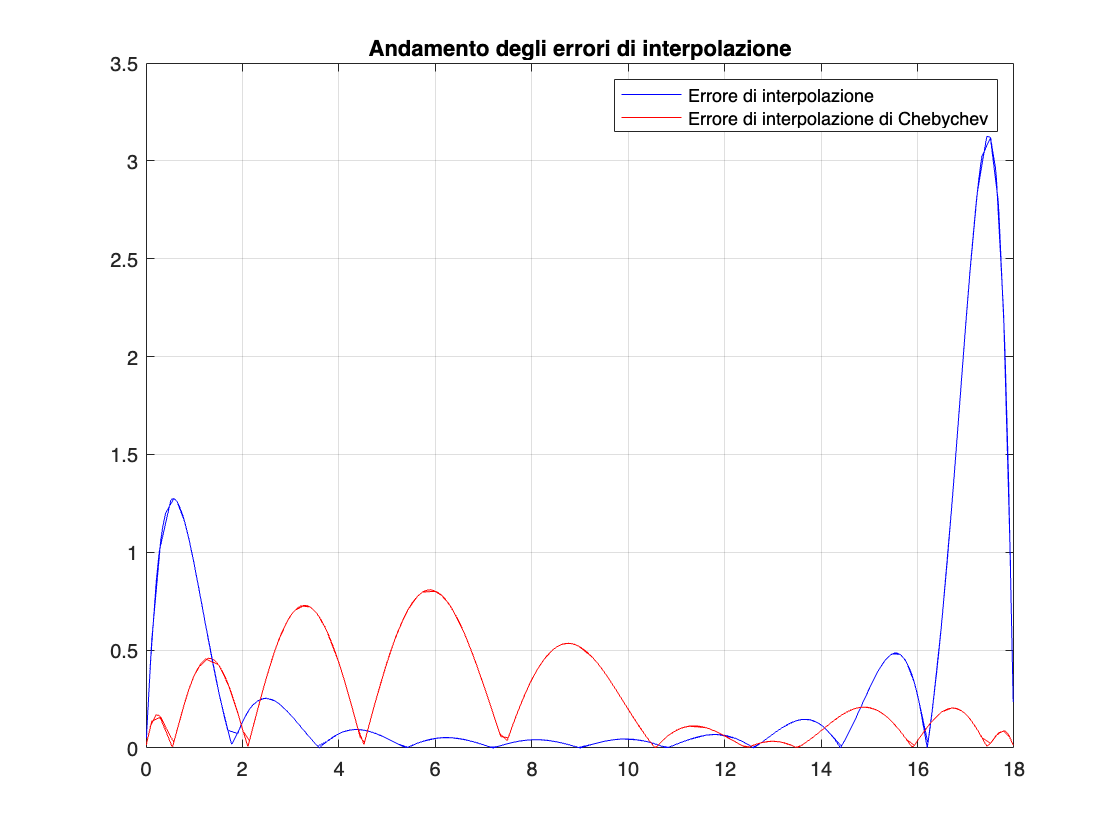

errIntC = abs(f(xx) - yy_cheb);
figure(6)
plot(xx, errInt, 'b', 'MarkerSize', 7)
hold on
grid on
plot(xx, errIntC, 'r', 'MarkerSize', 7)
title('Andamento degli errori di interpolazione')
legend('Errore di interpolazione', 'Errore di interpolazione di Chebychev')

errIntC < errInt

ans = 300×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Come possiamo vedere, sia dal risultato grafico che dal risultato numerico, l'errore di interpolazione con i nodi Chebychev sia diminuito di molto agli estremi rispetto all'errore di interpolazione calcolato in precedenza. Al centro invece l'errore aumentato leggermente, ma l'accuratezza è comunque molto buona.

#### Punto 1.6:

«*Considerare il poligono di *$N$*vertici costituito dai valori della curva parametrica interpolata al punto 1.2 e, tramite il comando *`fill, `*visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.*»

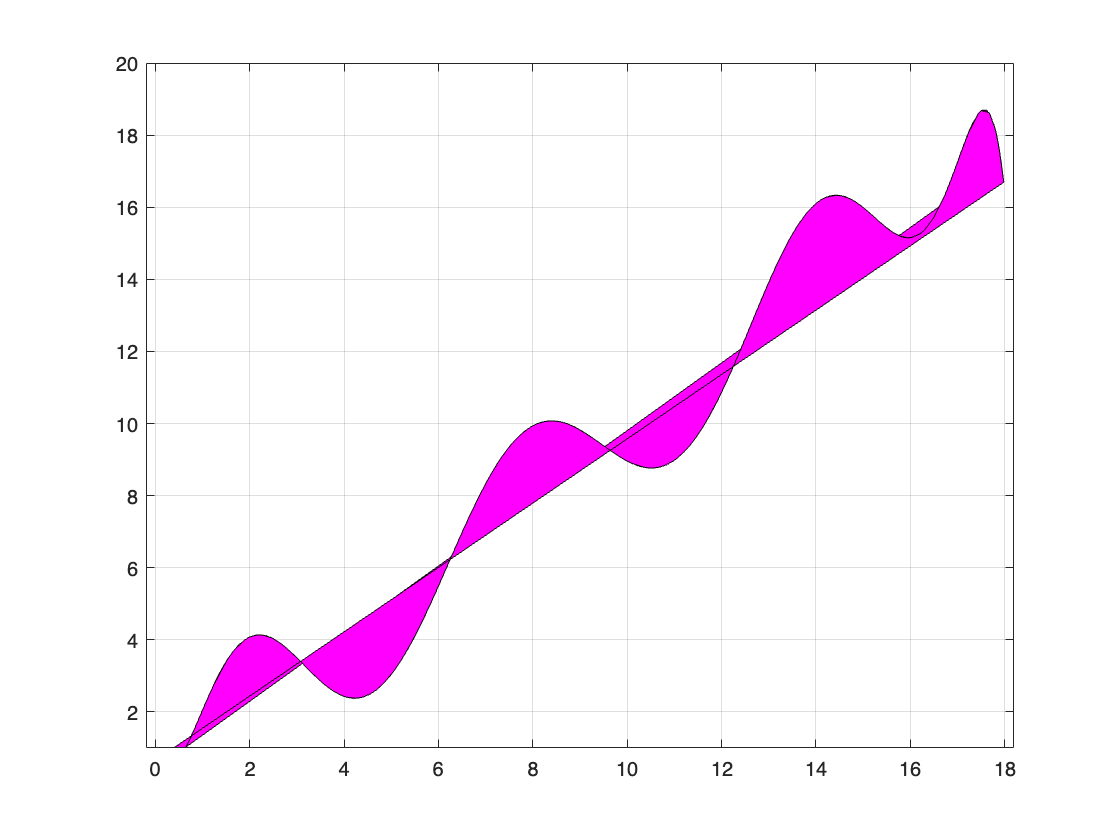

rgb = [1, 0, 1];
figure(7)
fill(xx, yy, rgb)
hold on
grid on
axis([a1 - 0.2, b1 + 0.2, 1, 20])

### Punto 2 – Interpolazione di curve parametriche:

«*Si considerino le seguenti curve parametriche:*

*         1. *$x = 5\cos(3\theta)\qquad y = 2\sin(3\theta)\qquad 0\leq \theta \leq 2\pi$

*         2. *$x = \theta^3 - 5\theta^2 + 3\theta - 11 \qquad y = \theta^2 - 2\theta + 3 \qquad -1 \leq \theta\leq 3$

*         3. *$x = 4\cos(\theta) - \cos(4\theta)\qquad y = 4\sin(\theta) - \sin(4\theta) \quad      0\leq \theta \leq 2\pi$$

*Scegliere una di tali curve e campionarla in *$n$* punti *$P=\{(x_i,y_i)\}_{i=1}^n$*, corrispondenti a *$n$* punti *$t_i$* equispaziati nell'intervallo *$[a,b]$* in cui varia il parametro *$t$* (fissare *$20<n<30$*).*»

Scelgo la prima curva:

curvaX = @(theta) 5 .* cos(3 .* theta);
curvaY = @(theta) 2 .* sin(3 .* theta);

Traccia alla mano, il parametro $\theta$ (theta) varia nell'intervallo $[0, 2\pi]$: è in questo intervallo che noi andiamo a definire i nostri *n *punti equispaziati.

theta = linspace(0, 2 * pi, 23);

#### Punto 2.1:

«*Costruire due spline parametriche *$p_x$* e *$p_y$* che interpolino rispettivamente i punti *$(t_i,x_i)$* e i punti *$(t_i, y_i)$*  (*$i = 1,\ldots, n$*).*»

px = curvaX(theta);
py = curvaY(theta);

#### Punto 2.2:

«*Valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.*»

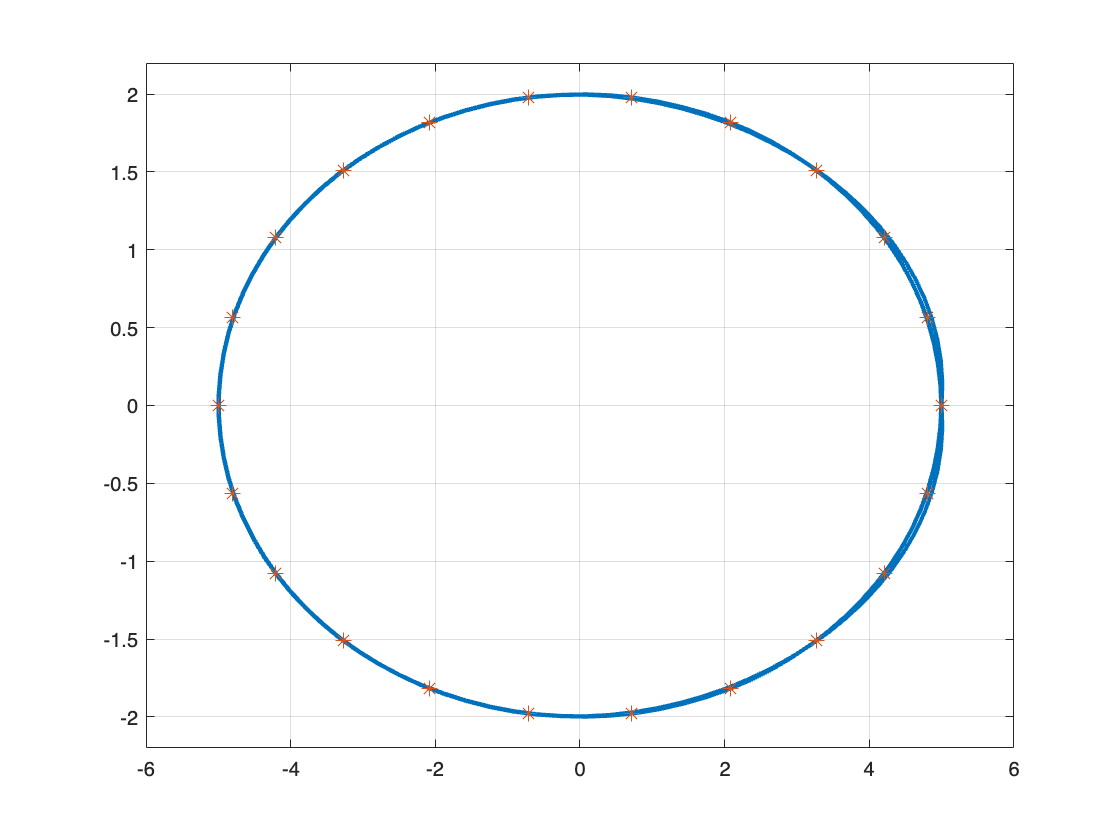

xxCurva = linspace(0, 2 * pi, 280);
xSpline = spline(theta, px, xxCurva);
ySpline = spline(theta, py, xxCurva);
figure(21)
plot(xSpline, ySpline, 'LineW', 2)
hold on
grid on
plot(px, py, '*', 'MarkerSize', 8)
axis([-6 6 -2.2 2.2])
hold off

#### Punto 2.3:

«*Ripetere i punti 2.1 e 2.2 su un insieme di *$m=40$* punti *$S = \{(x_j,y_j)\}_{j=1}^m$* le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando *`ginput`* usato su una immagine a propria scelta oppurtunamente caricata (usare *`imread). `*Le coordinate devono essere estese aggiungendo in coda un punto fittizio coincidente col primo punto, in modo tale che *`x`* e *`y`* siano i vettori delle coordinate dei vertici di un poligono (chiuso).*»

figure(22)
spada = imread("spada.jpeg");

Utilizzo la funzione `ginput` per prendere manualmente 40 punti. Ho commentato queste tre righe di codice perché mi servono solo per ottenere i punti e per evitare di riprenderli in esecuzioni successive.

%imshow("spada.jpeg")
%[spadaX, spadaY] = ginput(40)
%save('DatiHW2.mat', 'spadaX', 'spadaY');
load("DatiHW2.mat");

Creo dei nodi fittizi per chiudere la figura.

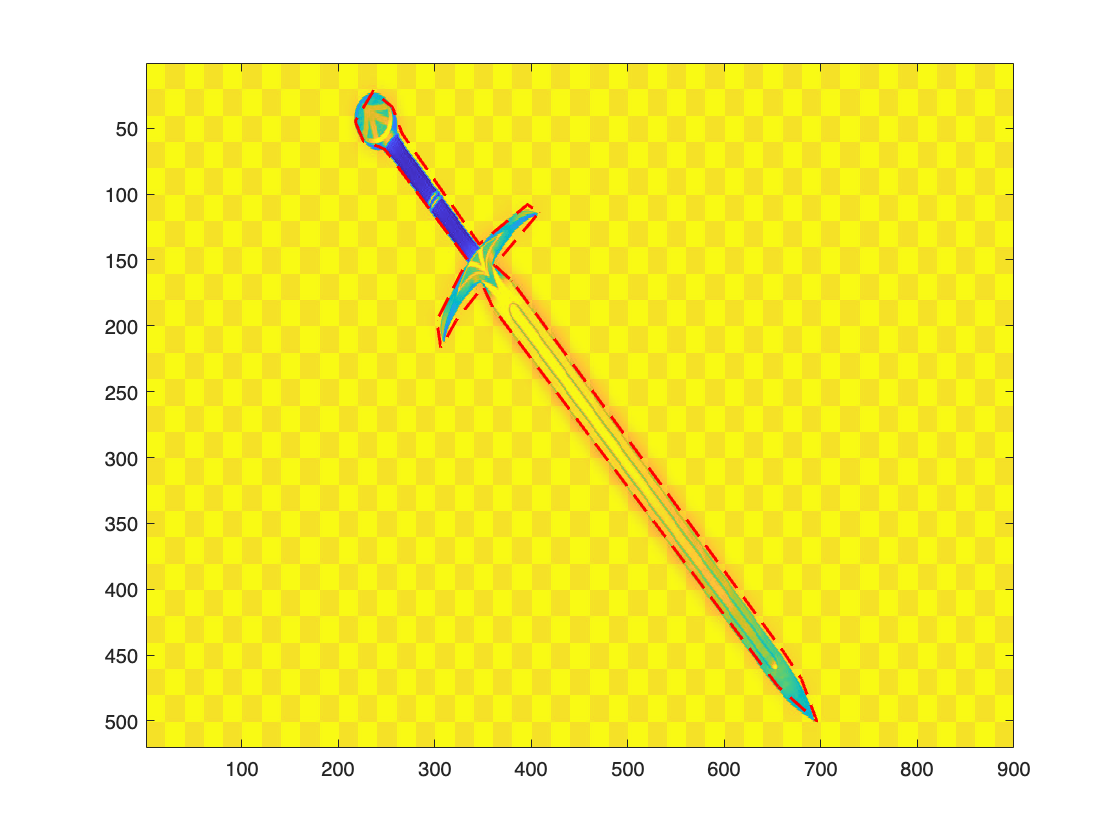

spadaX(end + 1) = spadaX(1);
spadaY(end + 1) = spadaY(1);
image(spada)
hold on
plot(spadaX, spadaY, '--r', 'LineWidth', 1.5);
hold off

Creo due spline sull'asse x e sull'asse y per creare la spline sulla curva parametrica rispetto a una variabile di tempo `t`.

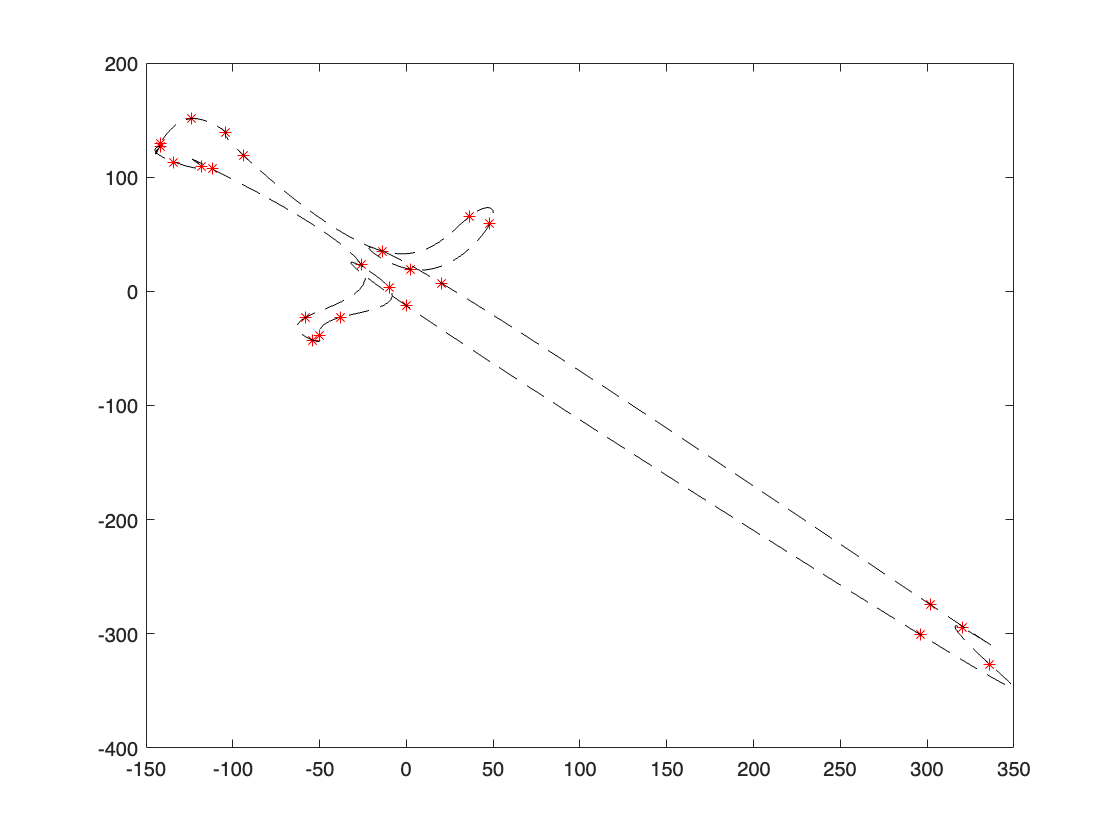

tSpada = 1 : length(spadaX);
ttSpada = linspace(tSpada(1), tSpada(end), 300);

% Aggiusto la figura graficamente
spadaX_centrato = mean(spadaX);
spadaY_centrato = mean(spadaY);
spadaX = spadaX - spadaX_centrato;
spadaY = - spadaY + spadaY_centrato;
spadaX_spline = spline(tSpada, spadaX, ttSpada);
spadaY_spline = spline(tSpada, spadaY, ttSpada);

figure(23)

plot(spadaX, spadaY, 'r*', spadaX_spline, spadaY_spline, '--k')

Il grafico è abbastanza accurato.

#### Punto 2.4:

«*Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file *`.mlx`»

La funzione `perimetro` è allegata in fondo al file.

perimetroSpada = perimetro(spadaX_spline, spadaY_spline)

perimetroSpada =      1.909497489459069e+03


#### Punto 2.5:

«*Ricostruire inoltre la curva parametrica passante per i punti definiti al punto 2.3 mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.*»

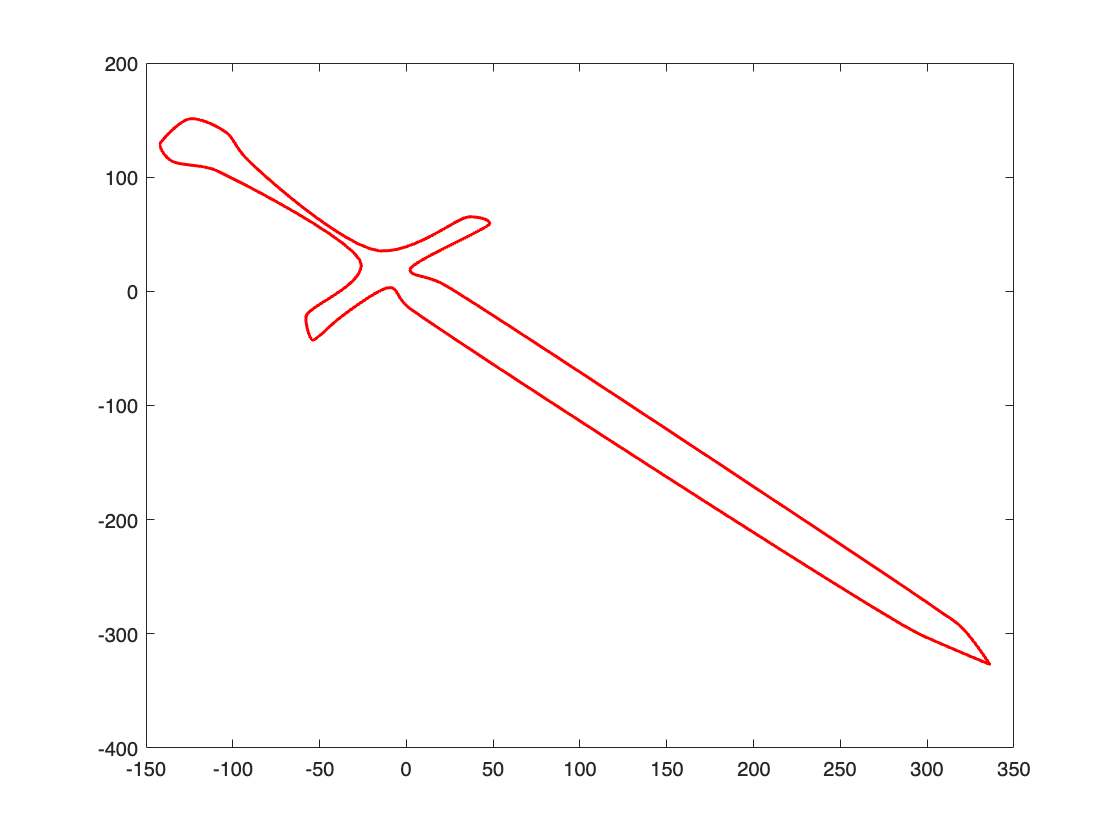

xxc = pchip(tSpada, spadaX, ttSpada);
yyc = pchip(tSpada, spadaY, ttSpada);
figure(24)
plot(xxc, yyc, 'r', 'LineWidth', 1.5)

Come possiamo vedere la spada viene correttamente ricostruita.

fprintf('Norma infinito del vettore: %d', norm(yyc, inf));

Norma infinito del vettore: 3.266715e+02

### Punto 3 – Approssimazione:

«*Generare un insieme di punti *$C=\{(t_i,y_i)\}_{i=1}^n$* le cui ascisse *$t_1,t_2,\ldots,t_n$* appartengono all'intervallo [3,4] e i valori  *$y_i$*  sono i valori perturbati della funzione *$f(t)=t^3-2t^2+4$* nei punti *$t_i$*, dove la perturbazione si intende introdotta aggiungendo un errore casuale tra 0 e 1 ad ogni valore *$y_i$*. Scegliere inoltre *$11 \leq n \leq 17$*.*»

functionT = @(t) t.^3 - 2 * t.^2 + 4;

% Parametri dell'intervallo
a2 = 3;
b2 = 4;

% Numero di punti da generare
n = 15;

% Generazione di punti casuali nell'intervallo [a, b]
xt = a2 + (b2 - a2) * rand(n, 1);

% Perturbazione dei valori aggiungendo un errore casuale tra 0 e 1
errore = rand(n, 1);
yt = functionT(xt) + errore;

#### Punto 3.1:

*«Costruire e valutare, su una griglia fitta di almeno 73 punti, utilizzando i metodi studiati, la cubica dei minimi quadrati approssimante i dati.»*

% Creazione della griglia fitta di punti
griglia = linspace(a2, b2, 73);

Bmat = [xt.^3, xt.^2, xt, ones(size(xt))];

a_mat = SGauss((Bmat' * Bmat), (Bmat' * yt));

% Costruisco la cubica dei minimi quadrati
cubicaMQ = polyval(a_mat, griglia);

#### Punto 3.2:

«*Mostrare graficamente sia il polinomio di terzo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.*»

Uno *scostamento *è la differenza tra la $y$ e la sua proiezione sulla cubica dei minimi quadrati.

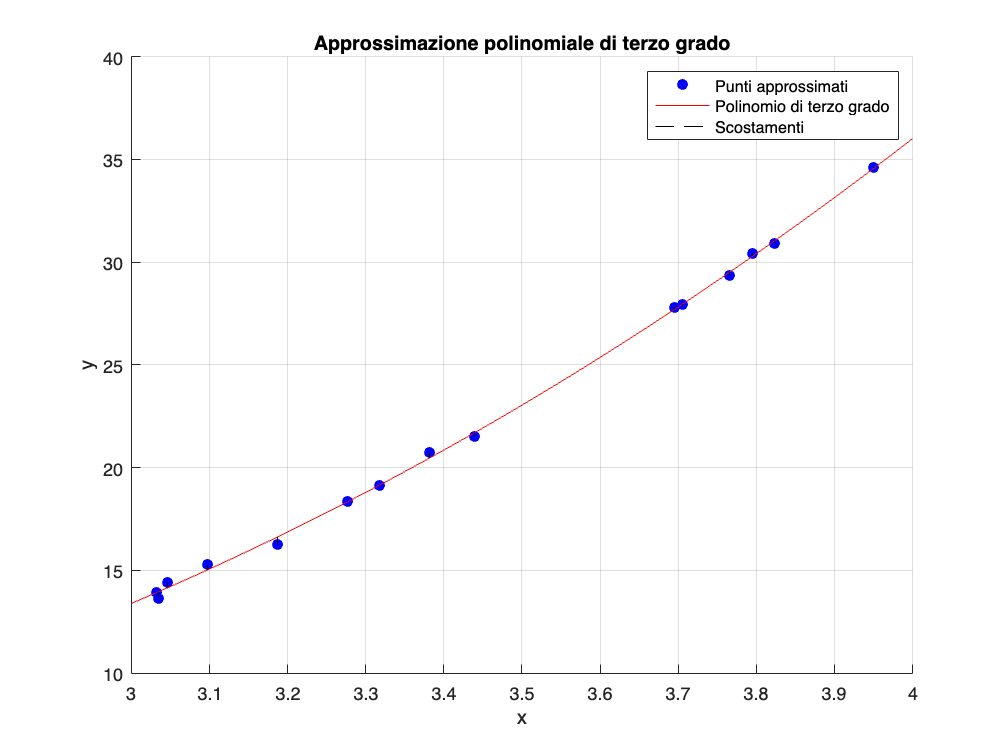

figure;
% Plot dei punti approssimati
scatter(xt, yt, 'b', 'filled');
hold on;

% Plot del polinomio di terzo grado approssimante
plot(griglia, cubicaMQ, 'r');

% Plot degli scostamenti come linee tratteggiate verticali
for i = 1:n
    plot([xt(i), xt(i)], [polyval(a_mat, xt(i)), yt(i)], 'k--');
end

hold off;

% Etichette e titolo del grafico
xlabel('x');
ylabel('y');
title('Approssimazione polinomiale di terzo grado');

% Legenda del grafico
legend('Punti approssimati', 'Polinomio di terzo grado', 'Scostamenti');

% Visualizzazione del grafico
grid on;

#### Punto 3.3:

«*Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 1 e 5. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.*»

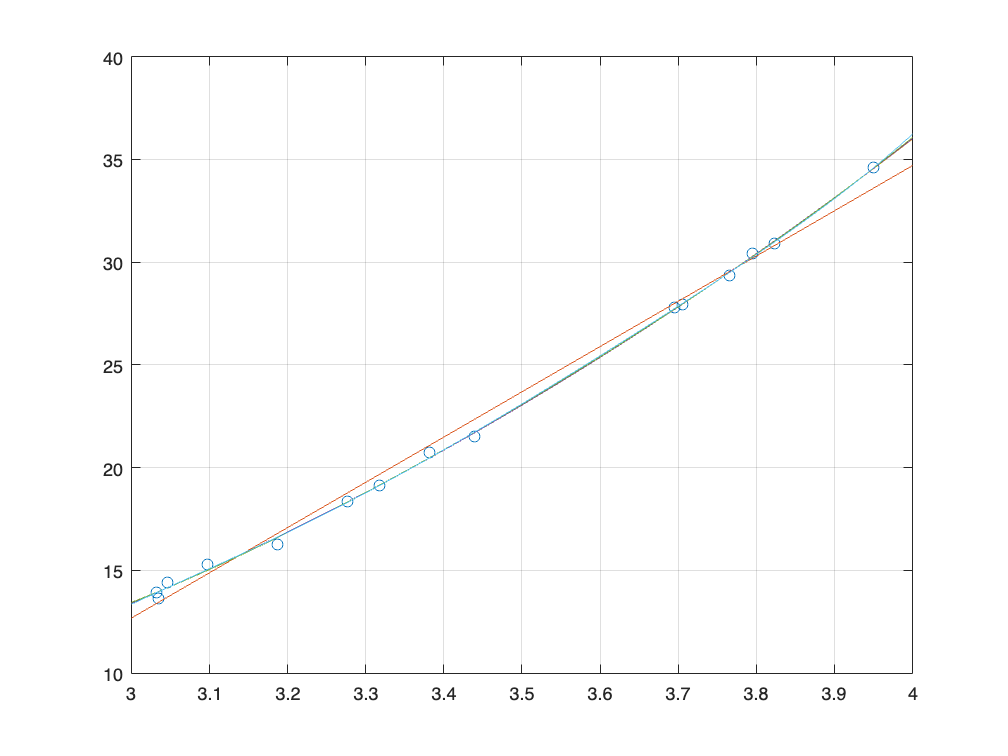

polinomi = zeros(length(griglia),5);
for i = 1 : 5
    polinomi(:, i)=(polyval(polyfit(xt, yt, i), griglia))';
end

figure;
plot(xt, yt, 'o', griglia, polinomi)

hold on
grid on

hold off

#### Punto 3.4:

«*Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.*»

resMQ = zeros(n,5);

for i = 1:5
    % calcolo dei residui dei polinomi MQ di grado 1:5
    resMQ(:,i) = norm(abs(polyval(polyfit(xt, yt, i), xt) - yt)', 2);
end

disp(resMQ)

    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318
    1.9446    0.7391    0.7389    0.7366    0.7318



### Punto 4 – Quadratura:

#### Punto 4.1:

«*Definire un dominio *$[a,b]$* ed una funzione composta *$f(x)$* in MATLAB combinando  le principali funzioni elementari. Assicurarsi che la funzione scelta sia positiva e continua nell'intervallo fissato *$[a,b]$*.*»

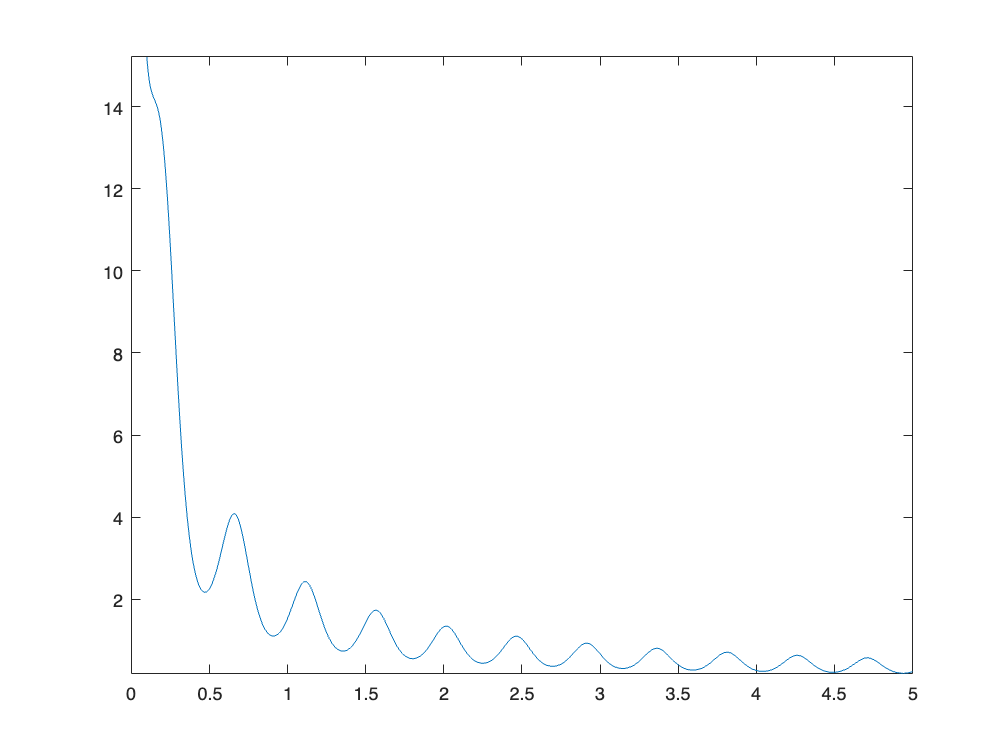

fun = @(x) exp(sin(7 .* x).^2 - log(x));
figure;
fplot(fun)

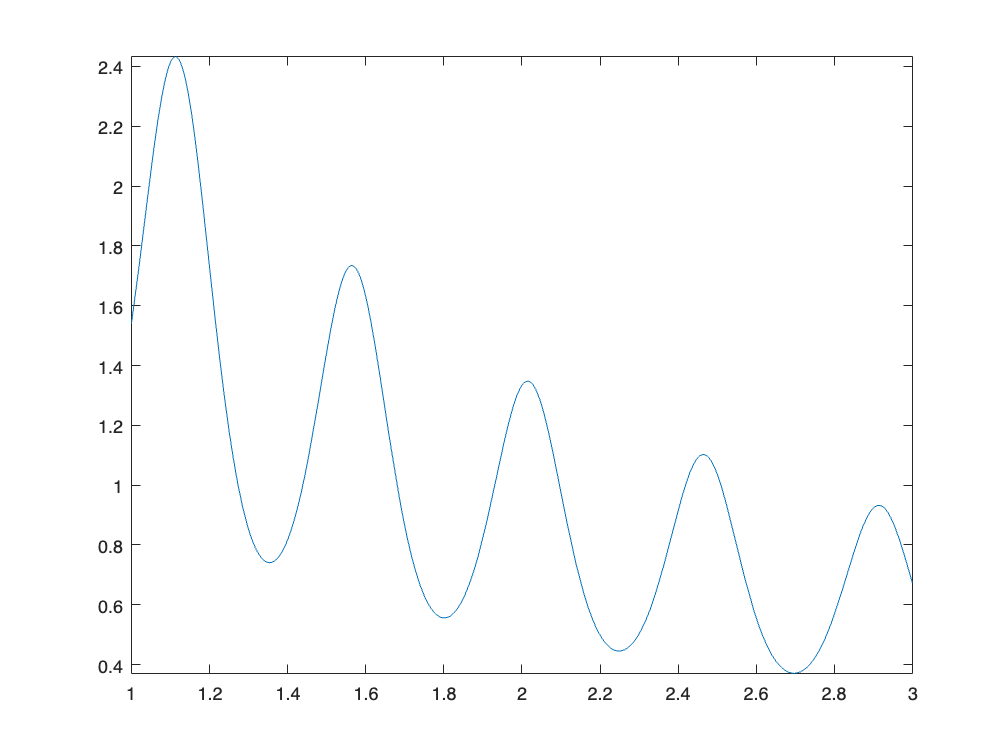

a1Quad = 1;
b1Quad = 3;
figure;
fplot(fun, [a1Quad, b1Quad])

#### Punto: 4.2:

«*Considerare *$I=I[f]=\int_a^b f(x)dx$* il valore ottenuto mediante la funzione MATLAB  integral con *$tol=10^{-9}$.»

integrale = integral(fun, a1Quad, b1Quad, 'AbsTol', 1e-9)

integrale = 2.0032

#### Punto 4.3:

«*Stimare l'integrale *$I$* utilizzando le formule di quadratura composite su m sottointervalli, relative alle seguenti  formule base: rettangolare destra, punto medio, Simpson, con m che varia tra le prime 5 potenze di 2 (1,2,4,8,16). Per ognuna di esse calcolare il corrispondente errore di discretizzazione.*»

% Definizione delle potenze di 2 per il numero di sottointervalli
m_values = 2.^(0:4);

methods = {'rettangolare destra', 'punto medio', 'simpson'};

% Calcolo dell'integrale e degli errori di discretizzazione per ogni formula base e numero di sottointervalli
for m = m_values
    disp(['Numero di sottointervalli: ', num2str(m)]);
    disp(' ');
    
    for method = methods
        disp(['Metodo di quadratura: ', char(method)]);
        
        h = (b1Quad - a1Quad) / m;
        
        switch char(method)
            case 'rettangolare destra'
                breaksRettDx = a1Quad + h .* [0:m];
                fbreaksRettDx = fun(breaksRettDx);
                integral_approx = h * sum(fbreaksRettDx(1:end - 1));

            case 'punto medio'
                breaks = a1Quad + h .* [0:m];
                puntiMedi = (breaks(1:end - 1) + breaks(2:end)) / 2;
                funPuntiMedi = fun(puntiMedi);
                integral_approx = h * sum(funPuntiMedi);

            case 'simpson'
                totalBreaks = a1Quad + h .* [0:m];
                puntiMediSimpson = totalBreaks(2:2:end - 1);
                estrSottoInt = totalBreaks(3:2:end - 2);
                funPuntiMediSimpson = fun(puntiMediSimpson);
                funEstrSottoInt = fun(estrSottoInt);
                f_a = fun(a1Quad); f_b = fun(b1Quad);
                integral_approx = (h / 3) * (f_a + 4 * sum(funPuntiMediSimpson) + 2 * sum(funEstrSottoInt) + f_b);

        end
        
        % Calcolo dell'errore di discretizzazione
        error_disc = abs(integral_approx - integrale);

        out_integrale = sprintf("Integrale approssimato: %.15f", integral_approx);
        out_errore = sprintf("Errore di discretizzazione: %.15f", error_disc);
        
        % Visualizzazione del risultato
        disp(out_integrale);
        disp(out_errore);
        disp(' ');
    end
end

Numero di sottointervalli: 1


Metodo di quadratura: rettangolare destra


Integrale approssimato: 3.079534876492926


Errore di discretizzazione: 1.076307098561329


Metodo di quadratura: punto medio


Integrale approssimato: 2.667930112931234


Errore di discretizzazione: 0.664702334999637


Metodo di quadratura: simpson


Integrale approssimato: 1.474008941394036


Errore di discretizzazione: 0.529218836537561


Numero di sottointervalli: 2


Metodo di quadratura: rettangolare destra


Integrale approssimato: 2.873732494712080


Errore di discretizzazione: 0.870504716780482


Metodo di quadratura: punto medio


Integrale approssimato: 2.481614421841237


Errore di discretizzazione: 0.478386643909639


Metodo di quadratura: simpson


Integrale approssimato: 2.515624545984508


Errore di discretizzazione: 0.512396768052910


Numero di sottointervalli: 4


Metodo di quadratura: rettangolare destra


Integrale approssimato: 2.677673458276658


Errore di discretizzazione: 0.674445680345061


Metodo di quadratura: punto medio


Integrale approssimato: 1.339983757859742


Errore di discretizzazione: 0.663244020071855


Metodo di quadratura: simpson


Integrale approssimato: 2.467566868731206


Errore di discretizzazione: 0.464339090799609


Numero di sottointervalli: 8


Metodo di quadratura: rettangolare destra


Integrale approssimato: 2.008828608068200


Errore di discretizzazione: 0.005600830136603


Metodo di quadratura: punto medio


Integrale approssimato: 2.069709948833736


Errore di discretizzazione: 0.066482170902139


Metodo di quadratura: simpson


Integrale approssimato: 1.713503535965225


Errore di discretizzazione: 0.289724241966373


Numero di sottointervalli: 16


Metodo di quadratura: rettangolare destra


Integrale approssimato: 2.039269278450969


Errore di discretizzazione: 0.036041500519371


Metodo di quadratura: punto medio


Integrale approssimato: 2.012464791389129


Errore di discretizzazione: 0.009237013457532


Metodo di quadratura: simpson


Integrale approssimato: 2.013227774228480


Errore di discretizzazione: 0.009999996296882


#### Punto 4.4:

«***Costruzione di formule di quadratura. ****Fissare *$p$*, nodi distinti (*$3 \leq p \leq 5$*), ****non*** ***equispaziati****, *$x_i \in [0,4]$*  di una formula di quadratura*

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

*per il calcolo numerico dell'integrale definito della funzione *$f$* in *$[0,4]$*.*»

p = 4;
a1Quad = 0; b1Quad = 4;

xQuad = (b1Quad - a1Quad) * rand(p, 1) + a1Quad;
xQuad = sort(xQuad);
I = ones(4, 1);

for i = 1 : p
    I(i, 1) = ((xQuad(end)^i - xQuad(1)^i) / i);
end

#### Punto 4.5:

«*Determinare i valori dei pesi *$w_i$* affinché la formula risulti esatta per polinomi algebrici di grado al più *$p-1$* (costruire e risolvere il sistema *$B^Tw=I$*.)*»

BQ = [ones(size(xQuad)), xQuad, xQuad.^2, xQuad.^3]'

BQ =     1.0000    1.0000    1.0000    1.0000
    0.5079    3.2589    3.6232    3.6535
    0.2580   10.6204   13.1273   13.3481
    0.1311   34.6107   47.5626   48.7673


w = SGauss(BQ, I);
Quadratura = sum(w(1 : 4) .* fun(xQuad(1 : 4)))

Quadratura = 13.2144

### Funzione per il calcolo del perimetro:

function perim = perimetro(x, y)
perim = sum(sqrt(diff(x).^2 + diff(y).^2));
end